# Intro on machine learning (vol II). fMRI.  

**Author**: Javier Ortiz-Tudela (Goethe University)

**Email**: [ortiztudela@psych.uni-frankfurt.de](mailto:ortiztudela@psych.uni-frankfurt.de)

**Created on**: 06/04/2020

**Last update on**: 12/04/2020

### Initialize some stuff.

Just run this section. Press Ctrl + Enter.

clear; close all
clc
load('beta_maps.mat')

## Intoduction

By now you should already know what beta maps are. If you do not, go back to the slides and excersies from previous sessions.

We have converted 16 beta maps from a LSA GLM into MATLAB formate so we can visualize them here. The cell below will display a few slices of this maps.

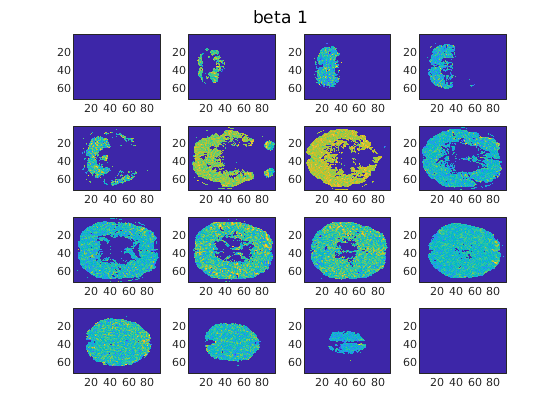

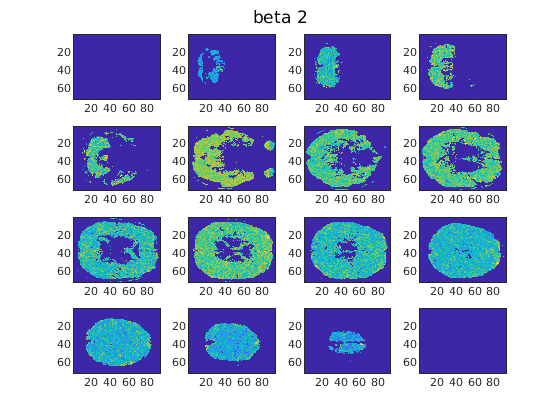

% Visualize two maps
for cBeta=1:2
    figure; c=1;
    for cImage=1:5:size(beta_maps{1},3)
        subplot(4,4,c), imagesc(beta_maps{cBeta}(:,:,cImage));
        c=c+1;sgtitle(['beta ', num2str(cBeta)]);
    end
end

### Feature (i.e., voxels) selection.

We have also included a mask of V1. Remember that a mask is just a file for selecting a given brain region. This file is a volume in which the values of the voxels for the region that we want to select are set to 1 while keeping the rest at 0.

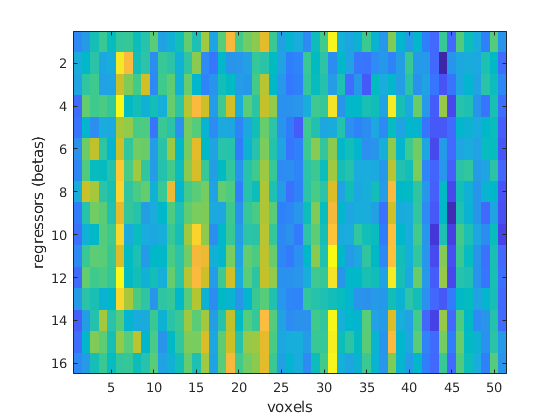

% This is the bit that selects the voxels. Do not worry too much about
% understanding how the loop works: we are interested here on the outcome.
for cBeta=1:length(beta_maps)
    sel_voxels(cBeta,:)=beta_maps{cBeta}(v1_mask==1);
end
sel_voxels(isnan(sel_voxels))=0;

% We can visualize our voxels as a matrix.
figure, imagesc(sel_voxels(:,150:200));
xlabel('voxels'); ylabel('regressors (betas)');

Do you understand this colorful matrix? We have our observations (betas) times our features (voxels) matrices. Remember, since we have used a LSA approach for estimating our beta maps, each beta here represents one trial.

In this experiment we showed people red and green shapes; these shapes could be either triangle and circles. Thus, we have 4 different trial types.

% Trial labels for every trial. 'g' stands for green; 'r' for red; 't' for
% triangle and 'c' for circle.
beta_labels={'gt'; 'rc'; 'gc'; 'rt'; 'rt'; 'gt'; 'rc'; 'gt';...
    'rt'; 'gc'; 'gc'; 'rc'; 'rt'; 'gc'; 'rc'; 'gt'}; % Change 5 and 9


ans = 4

ans = 4

ans = 4

ans = 4

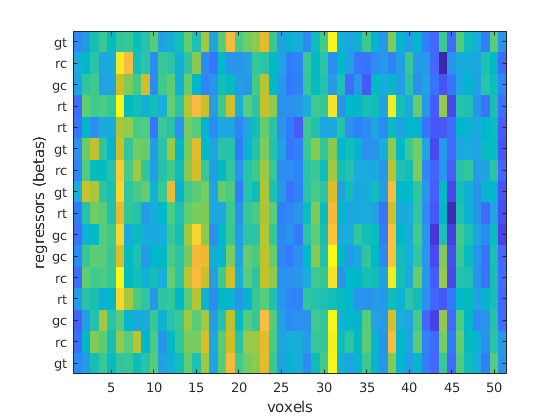

% Let's visualize them in the previous plot
imagesc(sel_voxels(:,150:200));
xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);

Now, let's say we want to test whether there is **shape information** in V1. We would be classifying between triangles and circles. We need to re-code our labels to reflect our classification analysis.

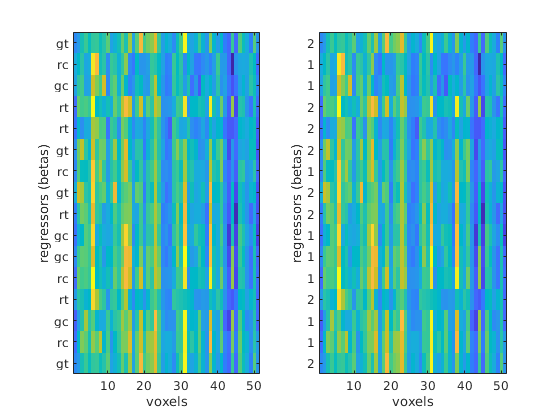

% Turn old labels into 1s and 2s.
new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=2;
new_labels(strcmpi(beta_labels, 'gc'))=1;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Let's visualize the new labels together with the old ones
subplot(1,2,1), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);
subplot(1,2,2), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(new_labels);

Does the new coding look good to you? 

We are ready to do the classification. Let's held out 4 observations for test.

% Get test observations and their labels
test_data=sel_voxels(1:4,:);
test_labels=new_labels(1:4);

% Get training observations and their labels
train_data=sel_voxels(5:16,:);
train_labels=new_labels(5:16);

% Train the classifier
classifier = fitcsvm(train_data, train_labels);

% Test the classifier
class_prediction=predict(classifier, test_data);

% Compute performance
shape_acc=mean(class_prediction==test_labels)

shape_acc = 0.2500

How well did the classifier do? Would you say that it has *learned* anything?

Now we can also ask: is** color information **coded in our ROI? We need to re-code our labels to reflect our classification analysis

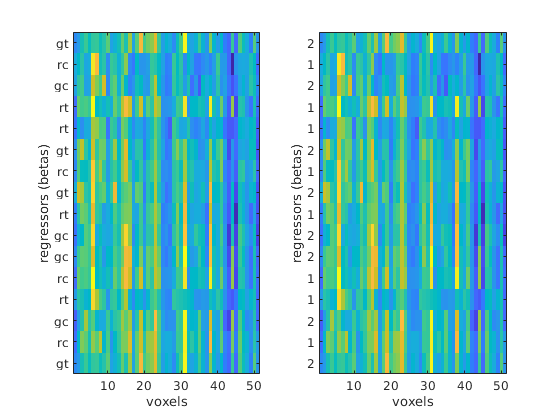

% Turn old labels into 1s and 2s.
new_labels=zeros(16,1);
new_labels(strcmpi(beta_labels, 'gt'))=2;
new_labels(strcmpi(beta_labels, 'rt'))=1;
new_labels(strcmpi(beta_labels, 'gc'))=2;
new_labels(strcmpi(beta_labels, 'rc'))=1;

% Let's visualize the new labels together with the old ones
subplot(1,2,1), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(beta_labels);
subplot(1,2,2), imagesc(sel_voxels(:,150:200)); xlabel('voxels'); ylabel('regressors (betas)');
yticks(1:16);yticklabels(new_labels);

Does the new coding look good to you? 

We are ready to do the classification. Let's held out 4 observations for test.

test_data=sel_voxels(1:4,:);
test_labels=new_labels(1:4);

% Get training observations and their labels
train_data=sel_voxels(5:16,:);
train_labels=new_labels(5:16);

% Train the classifier
classifier = fitcsvm(train_data, train_labels);

% Test the classifier
class_prediction=predict(classifier, test_data);

% Compute performance
color_acc=mean(class_prediction==test_labels)

color_acc = 0.7500

How well did the classifier do now?

We can now perform something equivalent to a univariate analysis to get an intuition of differences between approaches. We only have one participant here so we will not be able to run a group level analysis. However, since we have estimated one beta per trial, we can get the mean activation value for our ROI in each condition and use each beta as an observation.

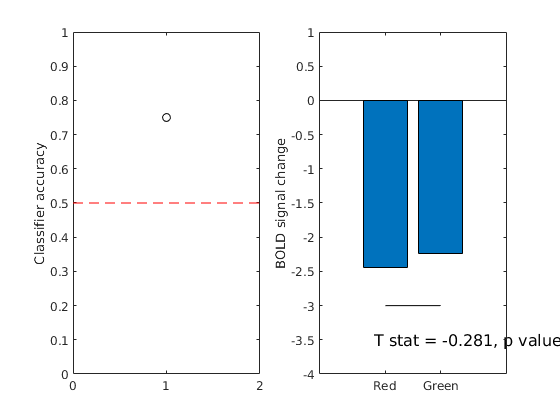

% Select the betas for each condition
red = sel_voxels(new_labels==1,:);
green = sel_voxels(new_labels==2,:);

% Compute the mean value in the ROI for each condition.
mean_activation_red = mean(red,2);
mean_activation_green = mean(green,2);

% We can use the different betas to run a coarse t test.
[~, p_value, ~, st]=ttest(mean_activation_red, mean_activation_green);

% Visualize the results of univariate and classification
subplot(1,2,1), plot(color_acc, 'ko');ylim([0 1]);ylabel('Classifier accuracy');line([0, 2],[.5 .5], 'LineStyle', '--', 'Color', 'r')
subplot(1,2,2),bar([mean(mean_activation_red), mean(mean_activation_green)]); ylabel('BOLD signal change');
ylim([-4, 1]); text(.8, -3.5, sprintf('T stat = %.3f, p value = %.3f', st.tstat, p_value),'FontSize', 12 )
xticklabels({'Red';'Green'});line([1 2],[-3 -3], 'Color', 'k')

Compare the univariate result to the classifier performance on the same data. Do they agree? If not, why do you think that might be?

### A few questions to think / discuss:

- What could you conclude from these results?

- Can you think of a way to statistically test for classifier perfomance?

- What would you consider *bad performance? *Hint: what indicates the red line in the pot?